# Plot Figure 2F, Figure 2 - supplementary 8

addpath(genpath('../public_code'))


nstrain_c57_set = {'male_before_timp_180511', ...
                   'male_c57_181012', ...
                   'male_c57_200701', ...
                   'male_before_bsa_200713'};



ttscheme = '1h';  ntest = 6; nNodes = 15; nStates = 4;
llh2_ntest = {};
llh2_alldata = {};
mi2 = {};
%%
s3 = {};

didf2 = [0, 4; 5, 9];
count = 0;
for i = 1:4 
    nstrain = nstrain_c57_set{i};
    for j = 1:2

        disp(['i = ' num2str(i) ', j = ' num2str(j)])
        count = count + 1; 
        di = didf2(j,1);
        df = didf2(j,2);

        sub_flag = 0;
        s2 = my_load_data(nstrain, di, df, sub_flag);

        s3{count} = s2;
        %%
        fp = ['sme_pairwise_l2_' nstrain '_di' num2str(di) ...
            '_df' num2str(df) '_' ttscheme '_beta0.mat'];
        load(fp,'jijFinal_alldata','hirFinal_alldata',...
            'jijFinal3','hirFinal3');

        llh2_alldata{count} = ...
            compute_loglikelihood(jijFinal_alldata, hirFinal_alldata, s2);

    end
end

i = 1, j = 1
i = 1, j = 2
i = 2, j = 1
i = 2, j = 2
i = 3, j = 1
i = 3, j = 2
i = 4, j = 1
i = 4, j = 2


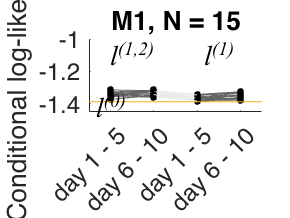

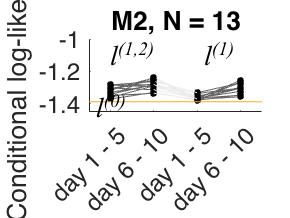

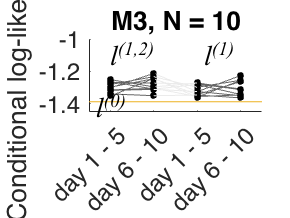

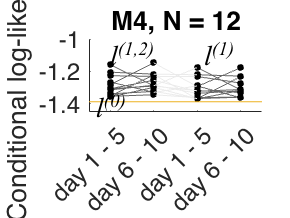

nNodes2 = [15, 13, 10, 12];

nCohorts = 4;
for icohort = 1:nCohorts
    figure()
    idata = (icohort-1)*2+1;
    jdata = icohort*2;
    for imice = 1:nNodes2(icohort)
        plot([1 2],...
            [llh2_alldata{idata}(3,imice); ...
            llh2_alldata{jdata}(3,imice)],...
            'Marker','.','markerSize',10,'MarkerFaceColor','k','MarkerEdgeColor','k',...
            'color',[0 0 0]+0.4)
        hold on
    
        plot([3 4],...
            [llh2_alldata{idata}(2,imice); ...
            llh2_alldata{jdata}(2,imice)],...
            'Marker','.','markerSize',10,'MarkerFaceColor','k','MarkerEdgeColor','k',...
            'color',[0 0 0]+0.4)
    
        plot([2 3] , ...
            [llh2_alldata{jdata}(3,imice); ...
            llh2_alldata{idata}(2,imice)],...
            'color',[0 0 0]+0.92)
    
    end
    
    
    
    set(gca,'ColorOrderIndex',3)
    plot([0.5 4.5],[1,1]*llh2_alldata{idata}(1,1))
    
    hold off
    xlim([0.5 4.5])
    
    txt = 'l^{(1,2)}';
    text(1.5, -1.1, txt,'FontSize',14,...
        'FontName','TimesNewRoman','FontAngle','italic',...
        'HorizontalAlignment','center')
    
    txt2 = 'l^{(1)}';
    text(3.5, -1.1, txt2,'FontSize',14,...
        'FontName','TimesNewRoman','FontAngle','italic',...
        'HorizontalAlignment','center')
    
    txt3 = 'l^{(0)}';
    text(0.6, -1.42, txt3,'FontSize',14,...
        'FontName','TimesNewRoman','FontAngle','italic',...
        'HorizontalAlignment','left')
    
    xticks(1:4)
    ylim([-1.45 -1.0])
    % yticks([-1.4 -1.35 -1.3])
    xticklabels({'day 1 - 5','day 6 - 10','day 1 - 5','day 6 - 10'})
    set(gca,'fontsize',12)
    xtickangle(45)
    ylabel('Conditional log-likelihood')
    title(['M' num2str(icohort) ', N = ' num2str(nNodes2(icohort))])
    
    box off
    
%     set(gcf, 'PaperUnits', 'inches');
%     set(gcf, 'PaperPosition', [0, 0, 3, 3]);  % 6 inches wide, 4 inches tall
%     set(gcf, 'PaperSize', [3, 3]);  
%     print(gcf, ['cll_5day_m' num2str(icohort) '.svg'], '-dsvg');

end

function s2 = my_load_data(nstrain, di, df, sub_flag)
if nargin < 4
    sub_flag = 0;
end

    s2 = [];
    for dayId = di:df
            
        fn = ['etho_' nstrain '_12hr_dt2s_d' num2str(dayId) '.mat'];
        
        load(fn,'s');
        s = s';
        s = int64(s);
        s = remove_tunnel(s);
        
        s = s(:,1801:12600);

        if sub_flag
            if strcmp(nstrain, 'male_after_bsa_200727')
                s = s([1:7 9:10],:); % no dead or immobilized mouse
            end

            if strcmp(nstrain, 'male_before_bsa_200713')
                s = s([1:2 4:8 10 12],:); % no dead or immobilized mouse
            end

            if strcmp(nstrain, 'female_before_timp_180413')
                s = s([1:12 14],:); % no dead or immobilized mouse
            end
        
            if strcmp(nstrain, 'female_after_timp_180430')
                s = s([1:12 14],:); % no dead or immobilized mouse
            end
        end


        s2 = [s2 s];
    end
end

function [s_train, s_test] = my_load_data_itest(nstrain, di, df, itest)
    s_train = [];
    s_test = [];
    for dayId = di:df
            
        fn = ['etho_' nstrain '_12hr_dt2s_d' num2str(dayId) '.mat'];
        
        load(fn,'s');
        s = s';
        s = int64(s);
        s = remove_tunnel(s);
        
        s = s(:,1801:12600);
        s2 = [s2 s];
    
        test_idx = (itest-1) * 1080+(1:1080);
        train_idx = setdiff(1:10800, test_idx);
        s_train = [s_train s(:, train_idx)];
        s_test = [s_test s(:, test_idx)];
    end
end


function [llh2] = compute_loglikelihood(jij, hir, s)
% return 3 rows, 1st row 1/4, 2nd row independent (only h), 3rd row
% pairwise

[nNodes, nSamples] = size(s);
nStates = 4;

llh2 = zeros(3, nNodes);
    
jijMat = recoverUpt(jij, nNodes);
hirMat = reshape(hir, nNodes, nStates-1);
hirMat = [hirMat zeros(nNodes,1)];


for imice = 1:nNodes
%%
    llh_null = log(1/nStates); 
    llh2(1, imice) = llh_null;

    m = mean(s(imice,:) == (1:nStates)',2);
    llh_indep = sum (log(m) .* m);
    llh2(2, imice) = llh_indep;
    
    % compute_local_energy1.
   
    llh_pw = 0; 
    for t = 1:nSamples
        mys = s(:, t);
        localE = compute_local_energy1(mys, imice, jijMat, hirMat);
        
        localE2 = zeros(1, nStates);
        mys_temp = mys;
        for istate = 1:nStates
            mys_temp(imice) = istate;
            localE2(istate) = compute_local_energy1(mys_temp, imice, jijMat, hirMat);
        end
        lh = exp(-localE) / sum(exp(-localE2));
        llh_pw = llh_pw + log(lh);
    end
    llh_pw = llh_pw / nSamples;
    llh2(3, imice) = llh_pw;
end

end


%% (from plot_figs13.mlx)
function [mi2] = compute_mi(s2, jij, hir)

%%
[nNodes, nSamples] = size(s2);
nStates = 4;

%%
[jijMat, hirMat] = matrix_form_jij_hir(jij, hir, nNodes, nStates);
localE3 = compute_localE3(s2, jijMat, hirMat, nStates);

%%
mi2 = zeros(nNodes,1); 
for imice = 1:nNodes
    m = mean(s2(imice,:) == (1:nStates)',2);
    entropy = - sum (m .* log2(m));
    
    ce2 = nan(1, nSamples);
    for isample = 1:nSamples
        myE = squeeze(localE3(imice, :, isample)) ;
        predProb = exp(-myE)./sum(exp(-myE));
        myCE = - sum(predProb .* log2(predProb));  % CE = conditional entropy
        ce2(isample) = myCE;
    end
    
    %%  
    mi2(imice) = entropy - mean(ce2);
end

end

function [jijMat, hirMat] = matrix_form_jij_hir(jij, hir, nNodes, nStates)
jijMat = recoverUpt(jij, nNodes);
hirMat = reshape(hir, nNodes, nStates-1);
hirMat = [hirMat zeros(nNodes,1)];

end

function [localE3] = compute_localE3(s2, jijMat, hirMat, nStates)
%%
[nNodes, nSamples] = size(s2);
localE3 = zeros(nNodes, nStates, nSamples);
for isample = 1:nSamples
    mys = s2(:,isample);
    for imice = 1:nNodes
        for istate = 1:nStates
            mys_temp = mys;
            mys_temp(imice) = istate;
            localE = compute_local_energy1(mys_temp, imice, jijMat, hirMat);
            localE3(imice, istate, isample) = localE;
        end
    end
end

end

